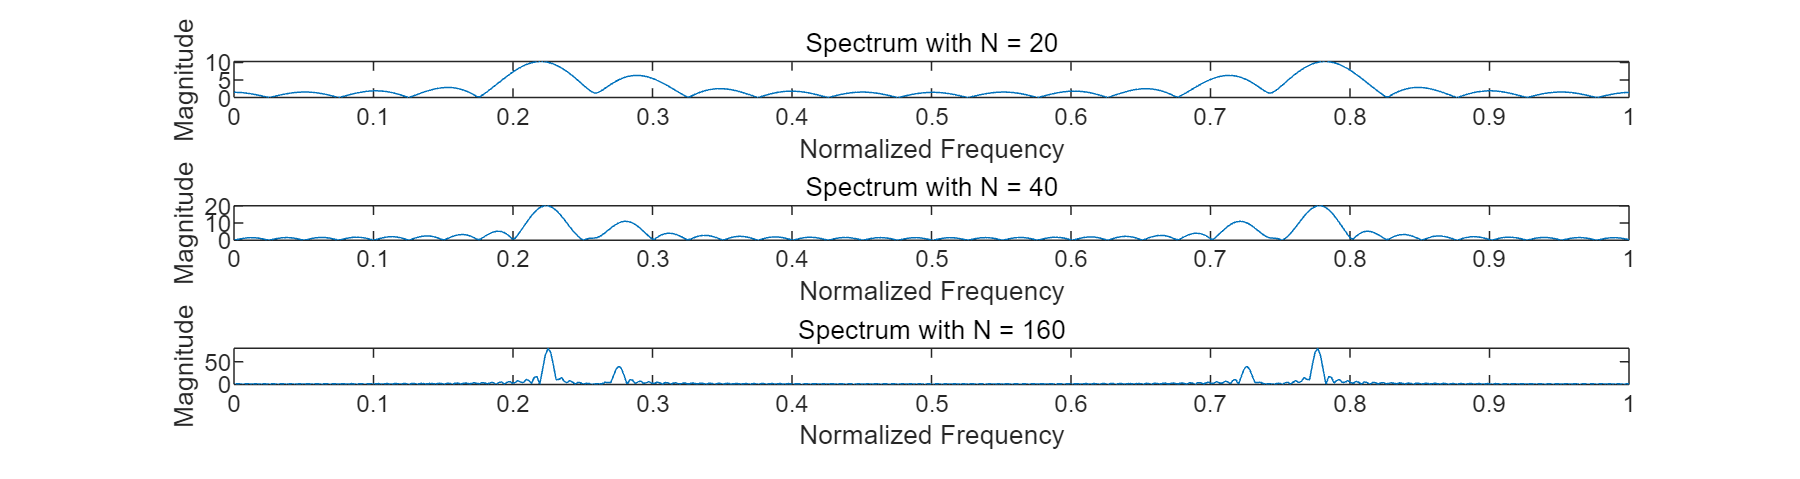

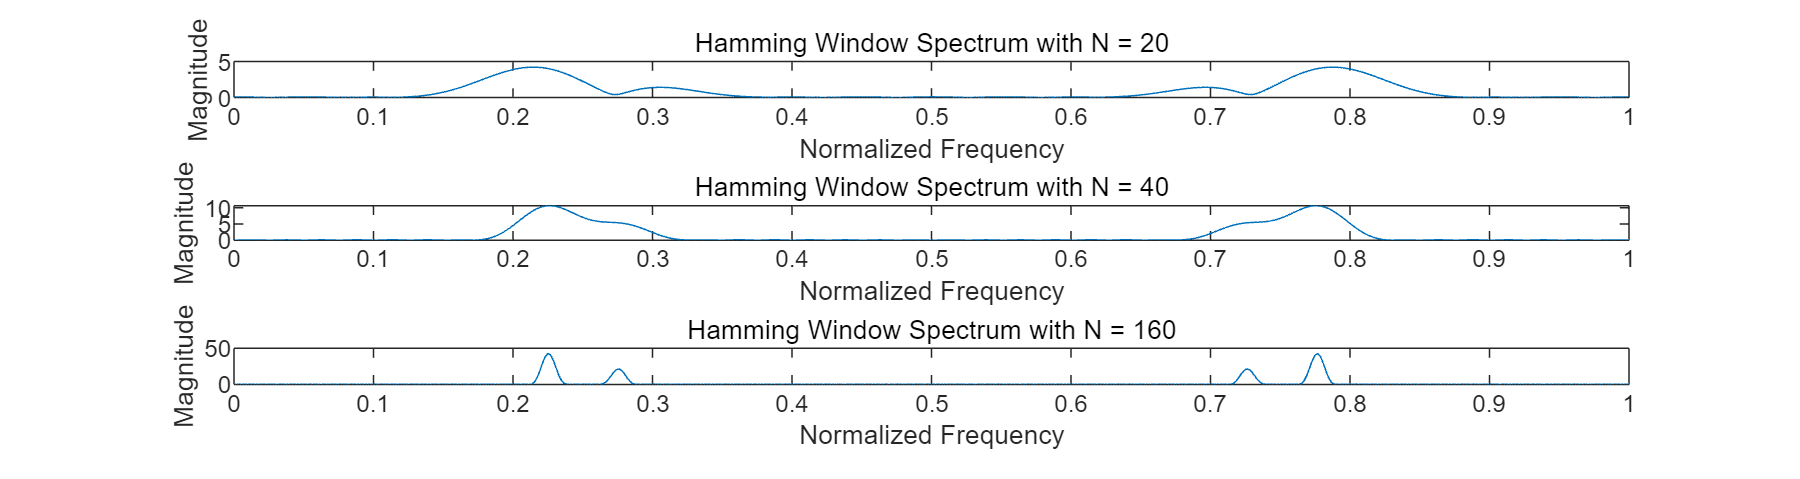

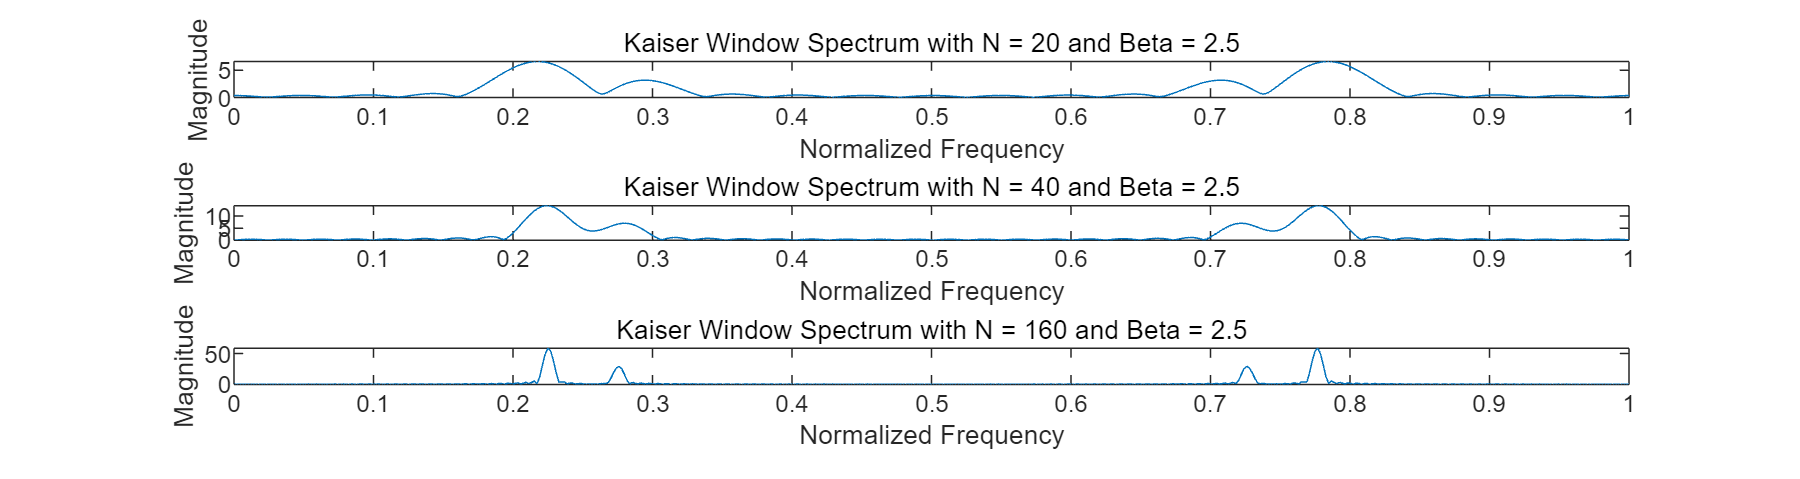

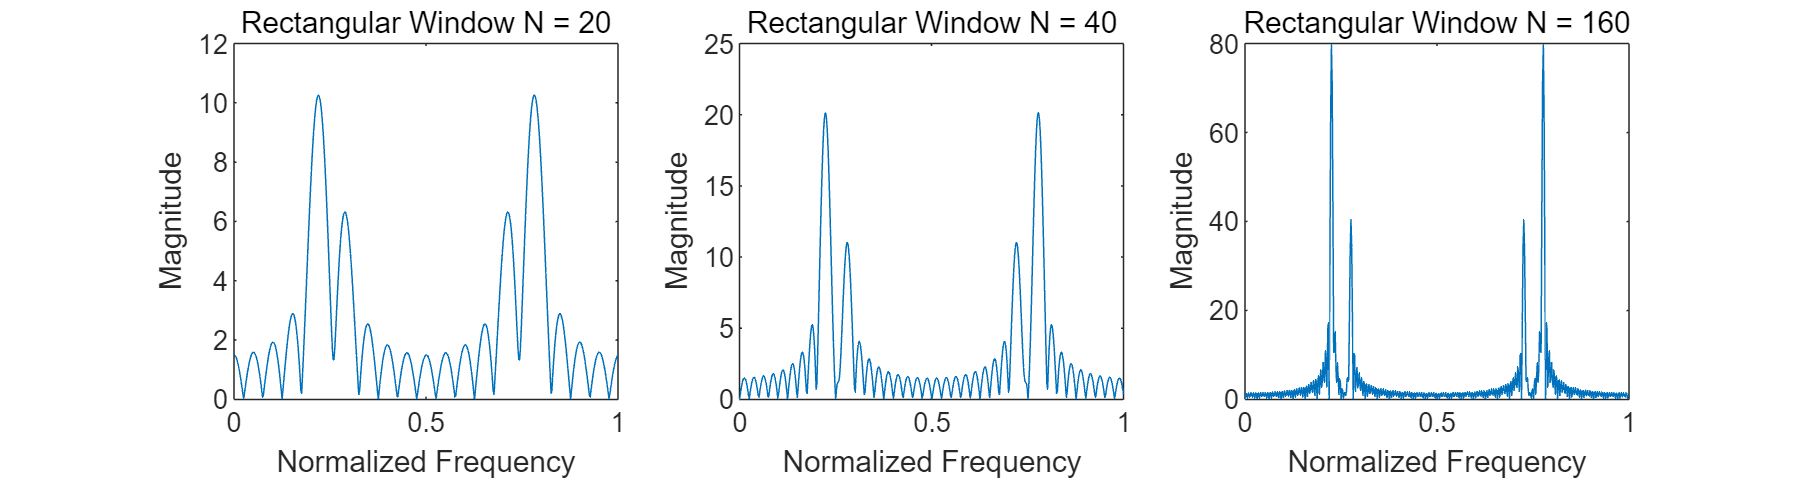

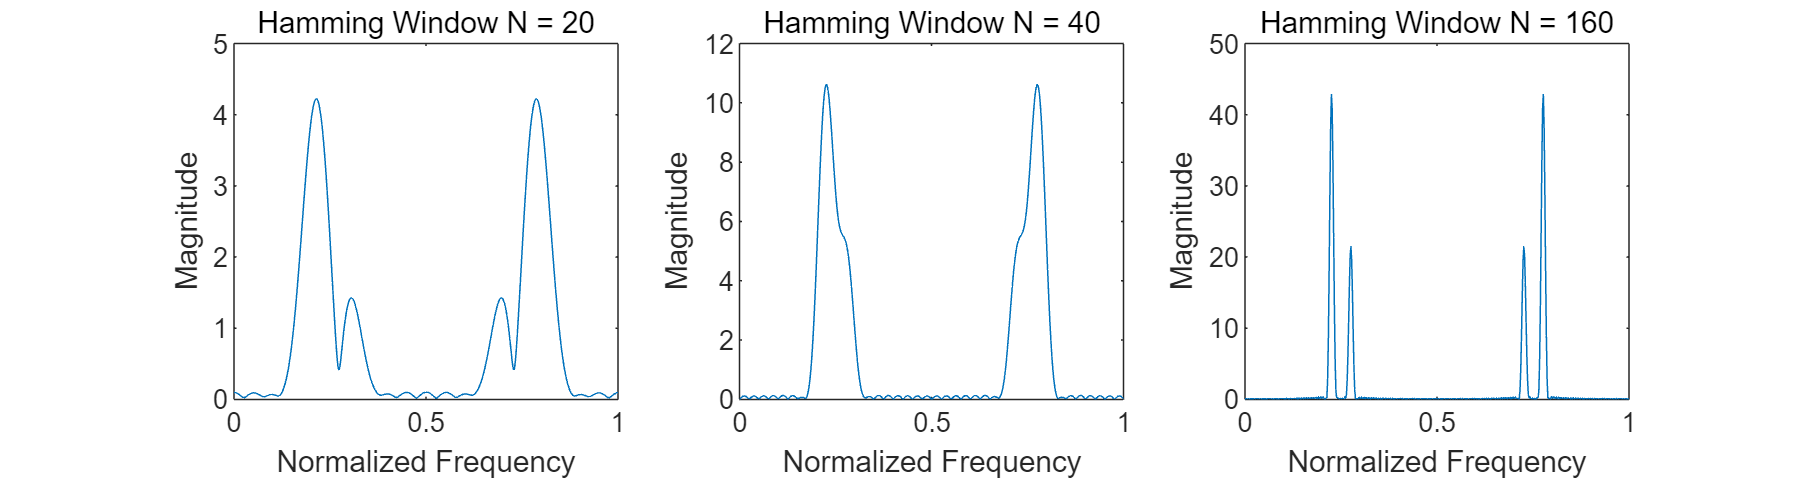

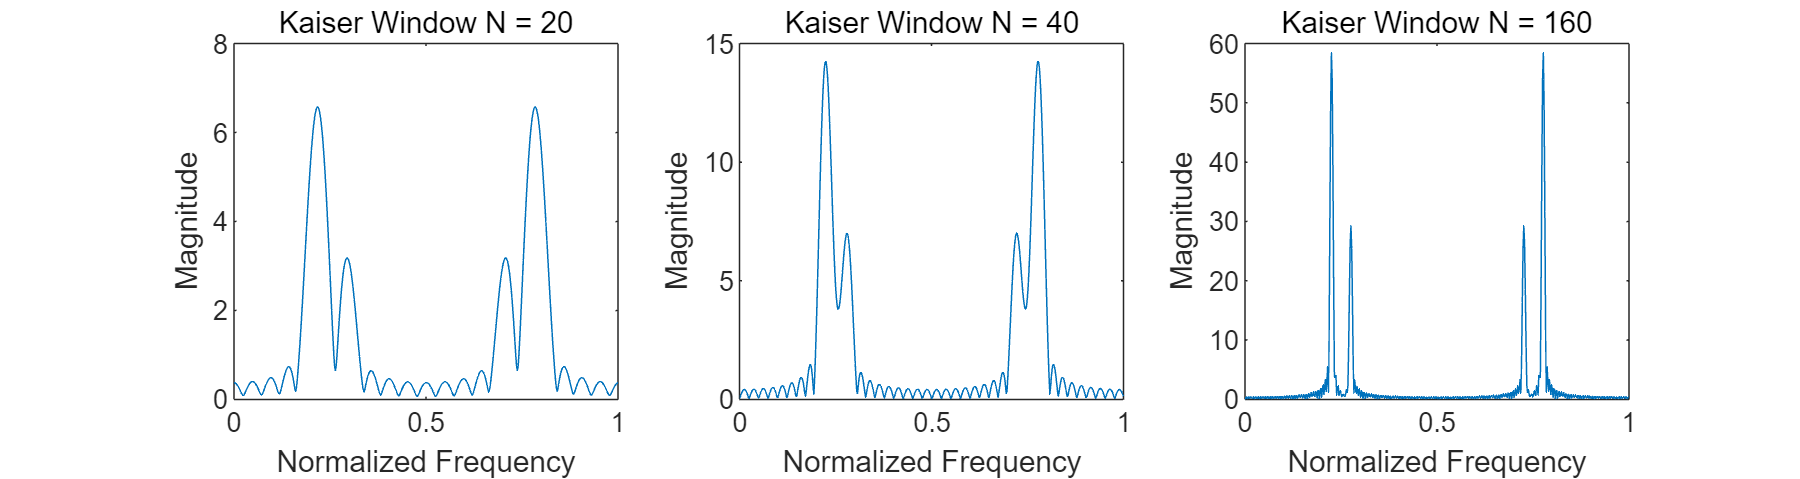

% LAB 2.1.1 刘兴琰 AI1 202264690069

k = 0:159; 
x_k = 0.5 * cos(11 * pi * k / 20) + cos(9 * pi * k / 20);

N = [20, 40, 160];

figure;

for i = 1:length(N)
    
    w = rectwin(N(i))';
    
   
    if length(w) < length(x_k)
        w = [w, zeros(1, length(x_k) - length(w))];
    end
    
    
    xw = x_k .* w;
    
    Xw = fft(xw, 512); 
    Xw_mag = abs(Xw); 
    

    subplot(length(N), 1, i);
    plot(linspace(0, 1, length(Xw_mag)), Xw_mag);
    title(['Spectrum with N = ', num2str(N(i))]);
    xlabel('Normalized Frequency');
    ylabel('Magnitude');
end
% LAB 2.1.2 刘兴琰 AI1 202264690069

k = 0:159; 
x_k = 0.5 * cos(11 * pi * k / 20) + cos(9 * pi * k / 20);

N = [20, 40, 160];

figure;

for i = 1:length(N)
    w = hamming(N(i))';
    
    if length(w) < length(x_k)
        w = [w, zeros(1, length(x_k) - length(w))];
    end
    
    xw = x_k .* w;
    
    Xw = fft(xw, 512); 
    Xw_mag = abs(Xw); 
    
    subplot(length(N), 1, i);
    plot(linspace(0, 1, length(Xw_mag)), Xw_mag);
    title(['Hamming Window Spectrum with N = ', num2str(N(i))]);
    xlabel('Normalized Frequency');
    ylabel('Magnitude');
end
% LAB 2.1.3 刘兴琰 AI1 202264690069

k = 0:159; 
x_k = 0.5 * cos(11 * pi * k / 20) + cos(9 * pi * k / 20);


N = [20, 40, 160];
beta = 2.5;  

figure;


for i = 1:length(N)
    
    w = kaiser(N(i), beta)';
    

    if length(w) < length(x_k)
        w = [w, zeros(1, length(x_k) - length(w))];
    end
    

    xw = x_k .* w;
    
    
    Xw = fft(xw, 512); 
    Xw_mag = abs(Xw); 
    

    subplot(length(N), 1, i);
    plot(linspace(0, 1, length(Xw_mag)), Xw_mag);
    title(['Kaiser Window Spectrum with N = ', num2str(N(i)), ' and Beta = ', num2str(beta)]);
    xlabel('Normalized Frequency');
    ylabel('Magnitude');
end

% LAB 2.1.4 刘兴琰 AI1 202264690069

k = 0:159;
x_k = 0.5 * cos(11 * pi * k / 20) + cos(9 * pi * k / 20);
N = [20, 40, 160];
beta = 2.5;

for i = 1:length(N)
    w_rect = rectwin(N(i))';
    w_ham = hamming(N(i))';
    w_kai = kaiser(N(i), beta)';
    
    windows = {w_rect, w_ham, w_kai};
    window_titles = {'Rectangular', 'Hamming', 'Kaiser'};
    
    for j = 1:length(windows)
        figure(j);
        set(gcf, 'Position', [100, 100, 1500, 400]); % Set the figure size, [left, bottom, width, height]
        
        w = windows{j};
        if length(w) < length(x_k)
            w = [w, zeros(1, length(x_k) - length(w))];
        end
        
        xw = x_k .* w;
        Xw = fft(xw, 512);
        Xw_mag = abs(Xw);
        
        subplot(1, length(N), i);
        plot(linspace(0, 1, length(Xw_mag)), Xw_mag);
        title([window_titles{j} ' Window N = ' num2str(N(i))]);
        xlabel('Normalized Frequency');
        ylabel('Magnitude');
    end
end